close all; clc; clearvars;

T_buenacalidad_revisadas = readtable('metadataCALIDADCORRECTA.csv');
[n, m] = size(T_buenacalidad_revisadas);

for i=1:20
roi = imread(['ROI', T_buenacalidad_revisadas.image{i}]);

red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
I_gray = rgb2gray(roi);

se = strel('disk', 30); 

canal_verde_sin_vasos = imclose(green_channel, se);
canal_rojo_sin_vasos = imclose(red_channel, se); %el canal rojo no tiene vasos
canal_azul_sin_vasos = imclose(blue_channel, se);
gray_sin_vasos = imclose (I_gray, se);

gray_sin_vasos1 = adapthisteq(gray_sin_vasos);
canal_azul_sin_vasos1 = adapthisteq(canal_azul_sin_vasos);
canal_verde_sin_vasos1 = adapthisteq(canal_verde_sin_vasos);
canal_rojo_sin_vasos1 = adapthisteq(canal_rojo_sin_vasos);

gray_sin_vasos2 = histeq(gray_sin_vasos);
canal_azul_sin_vasos2 = histeq(canal_azul_sin_vasos);
canal_verde_sin_vasos2 = histeq(canal_verde_sin_vasos);
canal_rojo_sin_vasos2 = histeq(canal_rojo_sin_vasos);

gray_sin_vasos3 = imadjust(gray_sin_vasos);
canal_azul_sin_vasos3 = imadjust(canal_azul_sin_vasos);
canal_verde_sin_vasos3 = imadjust(canal_verde_sin_vasos);
canal_rojo_sin_vasos3 = imadjust(canal_rojo_sin_vasos);

% figure; subplot(3,4,1); imshow(gray_sin_vasos1);
% subplot(3,4,2); imshow(canal_azul_sin_vasos1);
% subplot(3,4,3); imshow(canal_verde_sin_vasos1);
% subplot(3,4,4); imshow(canal_rojo_sin_vasos1);
% subplot(3,4,5); imshow(gray_sin_vasos2);
% subplot(3,4,6); imshow(canal_azul_sin_vasos2);
% subplot(3,4,7); imshow(canal_verde_sin_vasos2);
% subplot(3,4,8); imshow(canal_rojo_sin_vasos2);
% subplot(3,4,9); imshow(gray_sin_vasos3);
% subplot(3,4,10); imshow(canal_azul_sin_vasos3);
% subplot(3,4,11); imshow(canal_verde_sin_vasos3);
% subplot(3,4,12); imshow(canal_rojo_sin_vasos3);

e_gris = entropy(I_gray);
e_rojo = entropy(red_channel); % si es mas de 6 bien
e_verde = entropy(green_channel);
e_azul = entropy(blue_channel); % si es menos de 4 -> no usar %a partir de 6 no usar

e_gris1 = entropy(gray_sin_vasos1);
e_rojo1 = entropy(canal_rojo_sin_vasos1); 
e_verde1 = entropy(canal_verde_sin_vasos1);
e_azul1 = entropy(canal_azul_sin_vasos1);

e_gris2 = entropy(gray_sin_vasos2);
e_rojo2 = entropy(canal_rojo_sin_vasos2); 
e_verde2 = entropy(canal_verde_sin_vasos2);
e_azul2 = entropy(canal_azul_sin_vasos2);

if e_gris1 > 5 
    cup_threshold = 0.85 * max(gray_sin_vasos1(:)); % Umbral para la copa (brillo)
    
    cup_binary = gray_sin_vasos1 > cup_threshold; % Segmentación de la copa
else 
    cup_binary = ones(size(gray_sin_vasos));
end

if e_gris2 > 6
    disc_threshold = 0.9 * max(gray_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binary = gray_sin_vasos2 > disc_threshold; % Segmentación del disco completo
else 
    disc_binary = ones(size(gray_sin_vasos));
end

if e_rojo2 > 6
    disc_thresholdR = 0.95 * max(canal_rojo_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)

    disc_binaryR = canal_rojo_sin_vasos2 > disc_thresholdR; % Segmentación del disco completo
else 
    disc_binaryR = ones(size(gray_sin_vasos));
end

if e_verde2 > 5
    disc_thresholdG = 0.9 * max(canal_verde_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryG = canal_verde_sin_vasos2 > disc_thresholdG; % Segmentación del disco completo
else 
    disc_binaryG = ones(size(gray_sin_vasos));
end
 
if e_verde1 > 4.5 
    cup_thresholdG = 0.9 * max(canal_verde_sin_vasos1(:)); % Umbral para la copa (brillo)
  
    cup_binaryG = canal_verde_sin_vasos1 > cup_thresholdG; % Segmentación de la copa
else 
    cup_binaryG = ones(size(gray_sin_vasos));
end

if e_azul1 > 5.5 
    cup_thresholdB = 0.8 * max(canal_azul_sin_vasos1(:)); % Umbral para la copa (brillo)

    cup_binaryB = canal_azul_sin_vasos1 > cup_thresholdB; % Segmentación de la copa
else 
    cup_binaryB = ones(size(gray_sin_vasos));
end

if e_azul2 > 4
    disc_thresholdB = 0.9 * max(canal_azul_sin_vasos2(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryB = canal_azul_sin_vasos2 > disc_thresholdB; % Segmentación del disco completo
else 
    disc_binaryB = ones(size(gray_sin_vasos));
end

% Operación lógica de intersección para la segmentación de la copa
cup_binary_comun = cup_binary & cup_binaryG & cup_binaryB;

se = strel('disk', 5);
disc_binaryR = imdilate(disc_binaryR, se);
% Operación lógica de intersección para la segmentación del disco
disc_binary_comun = disc_binary & disc_binaryR & disc_binaryG  & disc_binaryB;

% figure; subplot(1,2,1); imshow(disc_binary_comun);
% subplot(1,2,2); imshow(cup_binary_comun);

se = strel('disk', 15);
disco = imerode(disc_binary_comun, se);
disco = bwareafilt(disco, 1);
disco = imdilate(disco, se);
copa = bwareafilt(cup_binary_comun, 1);
copa = imdilate(copa, se);

[fila, columna] = find(disco == max(disco(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_disco = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_disco = max(ancho_maximo, alto_maximo) / 2;

[fila, columna] = find(copa == max(copa(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_copa = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_copa = max(ancho_maximo, alto_maximo) / 2;

% figure; imshow(roi); title('Copa y disco')
subplot(4,5,i); imshow(roi); title(T_buenacalidad_revisadas.image{i+20});
hold on;
viscircles(centro_disco, radio_disco, 'EdgeColor', 'r', 'LineWidth', 2);
viscircles(centro_copa, radio_copa, 'EdgeColor', 'b', 'LineWidth', 2);
end

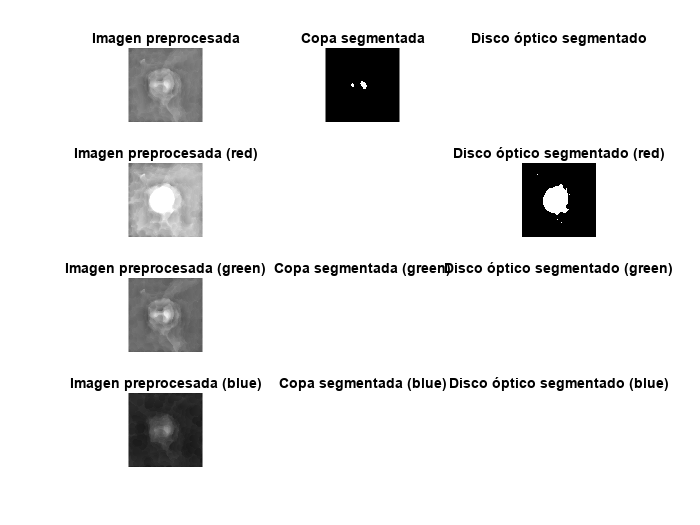

close all; clc; clearvars;
T_buenacalidad_revisadas = readtable('metadataCALIDADCORRECTA.csv');
[n, m] = size(T_buenacalidad_revisadas);

roi = imread(['ROI', T_buenacalidad_revisadas.image{21}]);

red_channel = roi(:, :, 1);
green_channel = roi(:, :, 2);
blue_channel = roi(:, :, 3);
I_gray = rgb2gray(roi);

se = strel('disk', 40); 

canal_verde_sin_vasos = imclose(green_channel, se);
canal_rojo_sin_vasos = imclose(red_channel, se); %el canal rojo no tiene vasos
canal_azul_sin_vasos = imclose(blue_channel, se);
gray_sin_vasos = imclose (I_gray, se);

gray_sin_vasos1 = adapthisteq(gray_sin_vasos);
canal_azul_sin_vasos1 = adapthisteq(canal_azul_sin_vasos);
canal_verde_sin_vasos1 = adapthisteq(canal_verde_sin_vasos);
canal_rojo_sin_vasos1 = adapthisteq(canal_rojo_sin_vasos);

gray_sin_vasos2 = histeq(gray_sin_vasos);
canal_azul_sin_vasos2 = histeq(canal_azul_sin_vasos);
canal_verde_sin_vasos2 = histeq(canal_verde_sin_vasos);
canal_rojo_sin_vasos2 = histeq(canal_rojo_sin_vasos);

e_gris = entropy(I_gray);
e_rojo = entropy(red_channel); % si es mas de 6 bien
e_verde = entropy(green_channel);
e_azul = entropy(blue_channel); % si es menos de 4 -> no usar %a partir de 6 no usar

e_gris1 = entropy(gray_sin_vasos1);
e_rojo1 = entropy(canal_rojo_sin_vasos1); 
e_verde1 = entropy(canal_verde_sin_vasos1);
e_azul1 = entropy(canal_azul_sin_vasos1);

e_gris2 = entropy(gray_sin_vasos2);
e_rojo2 = entropy(canal_rojo_sin_vasos2); 
e_verde2 = entropy(canal_verde_sin_vasos2);
e_azul2 = entropy(canal_azul_sin_vasos2);

if e_gris1 > 5 
    cup_threshold = 0.85 * max(gray_sin_vasos1(:)); % Umbral para la copa (brillo)
    
    cup_binary = gray_sin_vasos1 > cup_threshold; % Segmentación de la copa
else 
    cup_binary = ones(size(gray_sin_vasos));
end

if e_gris1 > 6 
    disc_threshold = 0.7 * max(gray_sin_vasos1(:)); % Umbral para el disco completo (menos brillo)

    disc_binary = gray_sin_vasos1 > disc_threshold; % Segmentación del disco completo
else 
    disc_binary = ones(size(gray_sin_vasos));
end

if e_rojo1 > 6
    disc_thresholdR = 0.9 * max(canal_rojo_sin_vasos1(:)); % Umbral para el disco completo (menos brillo)

    disc_binaryR = canal_rojo_sin_vasos1 > disc_thresholdR; % Segmentación del disco completo
else 
    disc_binaryR = ones(size(gray_sin_vasos));
end

if e_verde1 > 6
    disc_thresholdG = 0.6 * max(canal_verde_sin_vasos1(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryG = canal_verde_sin_vasos1 > disc_thresholdG; % Segmentación del disco completo
else 
    disc_binaryG = ones(size(gray_sin_vasos));
end
 
if e_verde1 > 6.5
    cup_thresholdG = 0.95 * max(canal_verde_sin_vasos1(:)); % Umbral para la copa (brillo)
  
    cup_binaryG = canal_verde_sin_vasos1 > cup_thresholdG; % Segmentación de la copa
else 
    cup_binaryG = ones(size(gray_sin_vasos));
end

if e_azul1 > 5.5 
    cup_thresholdB = 0.8 * max(canal_azul_sin_vasos1(:)); % Umbral para la copa (brillo)

    cup_binaryB = canal_azul_sin_vasos1 > cup_thresholdB; % Segmentación de la copa
else 
    cup_binaryB = ones(size(gray_sin_vasos));
end

if e_azul1 > 6 
    disc_thresholdB = 0.5 * max(canal_azul_sin_vasos1(:)); % Umbral para el disco completo (menos brillo)
    
    disc_binaryB = canal_azul_sin_vasos1 > disc_thresholdB; % Segmentación del disco completo
else 
    disc_binaryB = ones(size(gray_sin_vasos));
end

figure; subplot(4, 3, 1); imshow(gray_sin_vasos1); title('Imagen preprocesada');
subplot(4, 3, 2); imshow(cup_binary); title('Copa segmentada');
subplot(4, 3, 3); imshow(disc_binary); title('Disco óptico segmentado'); 
subplot(4, 3, 4); imshow(canal_rojo_sin_vasos1); title('Imagen preprocesada (red)');
% subplot(4, 3, 5); imshow(cup_binaryR); title('Copa segmentada (red)');
subplot(4, 3, 6); imshow(disc_binaryR); title('Disco óptico segmentado (red)'); 
subplot(4, 3, 7); imshow(canal_verde_sin_vasos1); title('Imagen preprocesada (green)');
subplot(4, 3, 8); imshow(cup_binaryG); title('Copa segmentada (green)');
subplot(4, 3, 9); imshow(disc_binaryG); title('Disco óptico segmentado (green)'); 
subplot(4, 3, 10); imshow(canal_azul_sin_vasos1); title('Imagen preprocesada (blue)');
subplot(4, 3, 11); imshow(cup_binaryB); title('Copa segmentada (blue)');
subplot(4, 3, 12); imshow(disc_binaryB); title('Disco óptico segmentado (blue)'); 

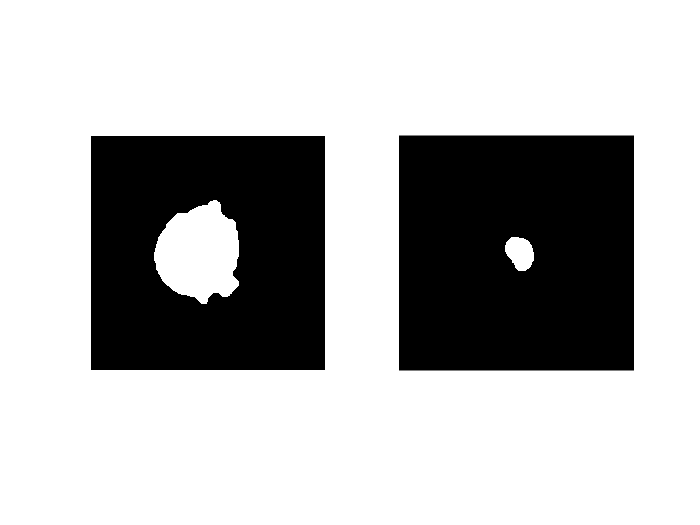


% Operación lógica de intersección para la segmentación de la copa
cup_binary_comun = cup_binary & cup_binaryG & cup_binaryB;

se = strel('disk', 10);
disc_binaryR = imdilate(disc_binaryR, se);
% Operación lógica de intersección para la segmentación del disco
disc_binary_comun = disc_binary & disc_binaryR & disc_binaryG  & disc_binaryB;

% figure; subplot(1,2,1); imshow(disc_binary_comun);
% subplot(1,2,2); imshow(cup_binary_comun);

se = strel('disk', 20);
disco = imerode(disc_binary_comun, se);
disco = bwareafilt(disco, 1);
disco = imdilate(disco, se);
copa = bwareafilt(cup_binary_comun, 1);
copa = imdilate(copa, se);

figure; subplot(1,2,1); imshow(disco);
subplot(1,2,2); imshow(copa);

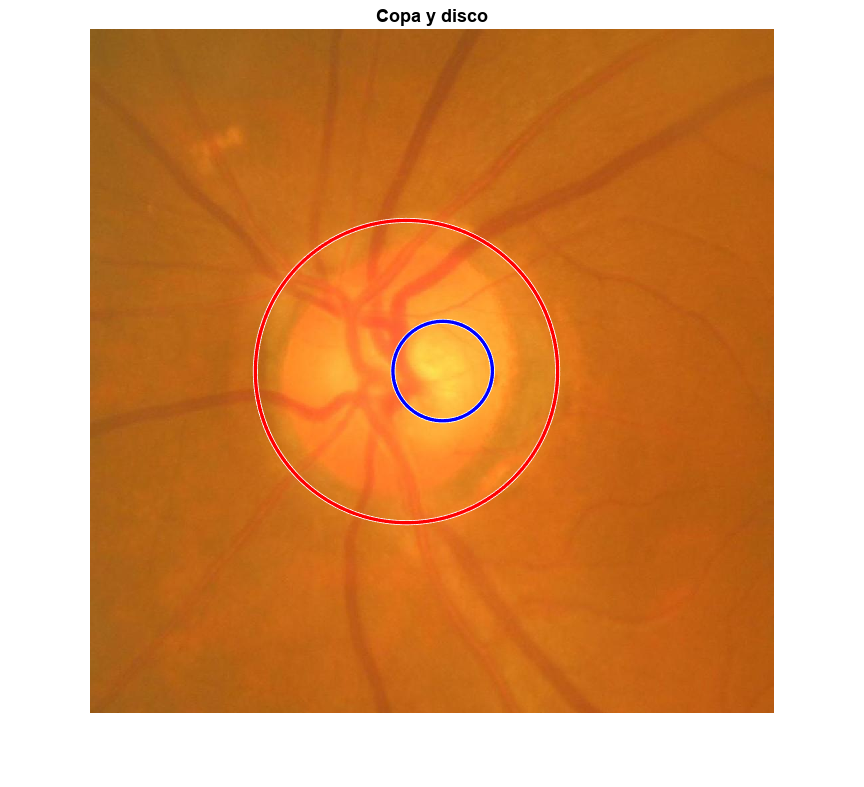


[fila, columna] = find(disco == max(disco(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_disco = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_disco = max(ancho_maximo, alto_maximo) / 2;

[fila, columna] = find(copa == max(copa(:)));
% Calcula el centroide
centroide_x = mean(columna);
centroide_y = mean(fila);
centro_copa = [centroide_x, centroide_y]; 
% Calcula el radio
ancho_maximo = max(fila) - min(fila);
alto_maximo = max(columna) - min(columna);
radio_copa = max(ancho_maximo, alto_maximo) / 2;

figure; imshow(roi); title('Copa y disco')
% subplot(4,5,i); imshow(roi); title(T_buenacalidad_revisadas.image{i});
hold on;
viscircles(centro_disco, radio_disco, 'EdgeColor', 'r', 'LineWidth', 2);
viscircles(centro_copa, radio_copa, 'EdgeColor', 'b', 'LineWidth', 2);